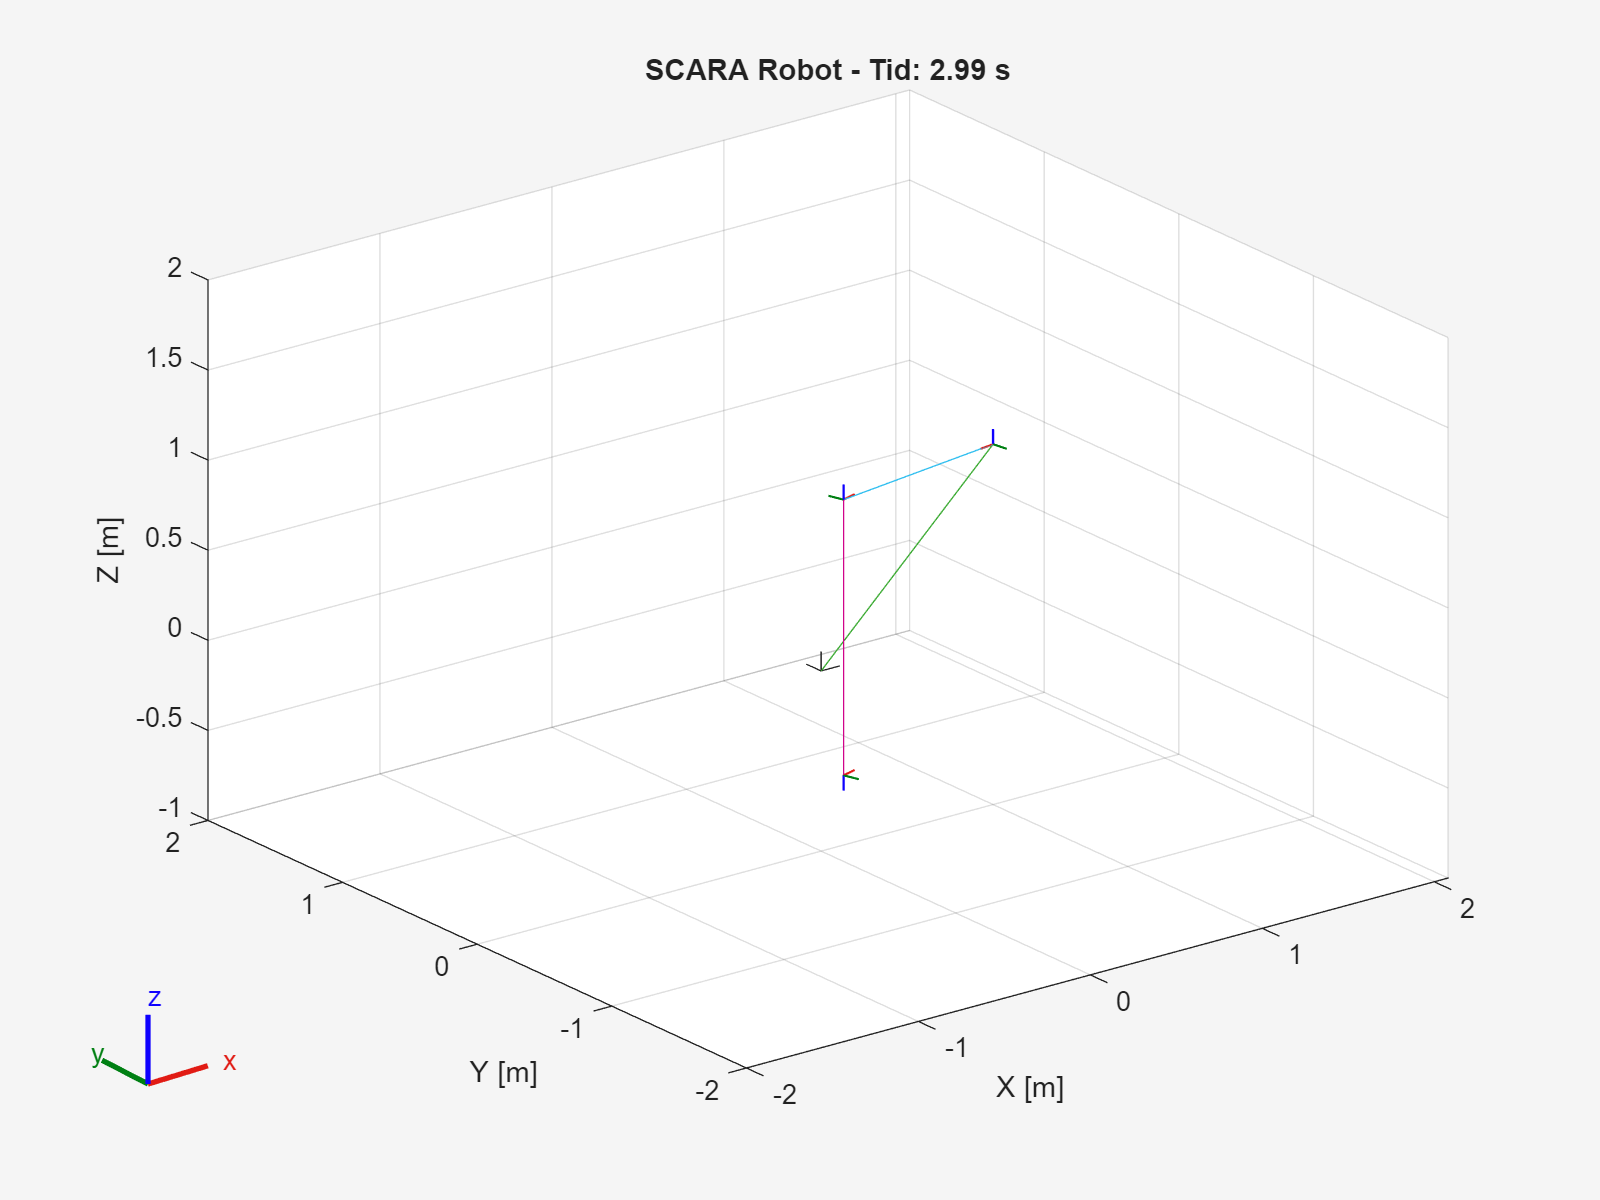


=== Endeefektor sluttposisjon ===
Pos: [0.011, -0.151, -0.531] m
RPY: [3.142, -0.000, 0.288] rad ([180.0°, -0.0°, 16.5°])


q0 = [pi/4; pi/6; 0.2];
Dq0 = [0; 0; 0];
x0 = [q0; Dq0];

q_des = [-pi; -pi; 1.6];
Dq_des = [0; 0; 0];

Kp = diag([100 100 200]);
Kd = diag([100 100 200]);

u_controller = @(t,q,Dq) Kp*(q_des - q) + Kd*(Dq_des - Dq) + [0; 0; 5];

tspan = [0 3];
odefun = @(t,x) SCARA_dynamics(t, x, u_controller);
[t, x] = ode45(odefun, tspan, x0);

q = x(:,1:3);

SCARA_animation(t,q);